clear
clc
close all

%% Change directory
% Get the full path of the currently running script
if isdeployed
    % If the code is deployed, use the built-in method
    scriptFullPath = mfilename('fullpath');
else
    % If running in the MATLAB environment, use the editor API
    scriptFullPath = matlab.desktop.editor.getActiveFilename;
end

% Extract the directory part of the path
[scriptDir, ~, ~] = fileparts(scriptFullPath);

% Change the current directory to the script's directory
cd(scriptDir);

% Display the current directory to confirm the change
disp(['Current directory changed to: ', scriptDir]);

Current directory changed to: C:\Users\giaco\Git_Repositories\Semester_Thesis_1\Data\Heat Pump


% Hot side temperature in °C in the data
data25 = readtable('Data/Heat Pump/temperature25.xlsx');
data50 = readtable('Data/Heat Pump/temperature50.xlsx');
data75 = readtable('Data/Heat Pump/temperature75.xlsx');

data = vertcat(data25, data50, data75);

## Regressions

Linear

% mdl.Coefficients.Estimate
%x1 = current
%x2 = delta T
%x3 = T hot side in K
X = [data.Current_A, data.DeltaT_C, convtemp(data.Th_C, 'C', 'K')];

y1 = data.Qremoved_W;
mdl_Q_removed = fitlm(X, y1, 'y ~ x1:x3 + x1:x2 + x1^2 + x2 + x3 - x1')

mdl_Q_removed = Linear regression model:
    y ~ 1 + x2 + x3 + x1:x2 + x1:x3 + x1^2

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -2.4011       0.20736    -11.579    5.6786e-30
    x2              -0.25813    0.00086214    -299.41             0
    x3              0.010009    0.00067153     14.904    1.6899e-47
    x1:x2          -0.026243    0.00022451    -116.89             0
    x1:x3           0.029467    8.0958e-05     363.98             0
    x1^2            -0.63885     0.0035584    -179.54             0


Number of observations: 1834, Error degrees of freedom: 1828
Root Mean Squared Error: 0.541
R-squared: 0.9

% mdl_Q_removed = fitlm(X, y1, 'y ~ x1*x2*x3 + x1^2 + x2^2 - x1:x2:x3');

y2 = data.Qwaste_W;
mdl_Q_waste = fitlm(X, y2, 'y ~ x1*x2*x3 - x1:x2:x3');

y3 = data.Voltage_V;
mdl_voltage = fitlm(X, y3, 'y ~ x1 + x2 + x3')

mdl_voltage = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate        SE         tStat     pValue
                   ________    __________    _______    ______

    (Intercept)     -6.0762      0.099282    -61.202      0   
    x1               1.3175     0.0033189     396.98      0   
    x2              0.01984    0.00021159     93.765      0   
    x3             0.020084     0.0003052     65.807      0   


Number of observations: 1834, Error degrees of freedom: 1830
Root Mean Squared Error: 0.266
R-squared: 0.99,  Adjusted R-Squared: 0.99
F-statistic vs. constant model: 6.12e+04, p-value = 0

% mdl_voltage = fitlm(X, y3, 'y ~ x1*x2*x3 - x2:x3 - x1:x2:x3');

Nonlinear

y4 = data.COP;

modelFun = @(b, X) ((b(1)*X(:,1).^3 + b(2)*X(:,1).^2 + b(3)*X(:,1) + b(4)) ./ ...
                   (b(5)*X(:,1).^3 + b(6)*X(:,1).^2 + b(7)*X(:,1) + b(8))) + ...
                   (b(9)*X(:,2).^2 + b(10)*X(:,2) + b(11)) + ...
                   (b(12)*X(:,3));

initialGuess = [-70, 900, 1500, -490, 145, 292, 61, 0, 1, 1, 1, 1];

mdl_COP = fitnlm(X, y4, modelFun, initialGuess);

# Plot

curr    = linspace(1,6,6);              %A
deltaT  = linspace(0,60,7);             %K
T_hot   = linspace(25,75,3);            %°C
T_hot_K = convtemp(T_hot, 'C', 'K');    %K

curr_str    = string(curr);
deltaT_str  = string(deltaT);
T_hot_str   = string(T_hot);

curr_len    = length(curr_str);
deltaT_len  = length(deltaT_str);
T_hot_len   = length(T_hot_str);

curr_colormap   = flipud(winter(curr_len));
deltaT_colormap = flipud(autumn(deltaT_len));
T_hot_colormap  = flipud(autumn(T_hot_len));

% Electrical power
label_P_el = "Electrical power / W";

% Dictionary for the labels
headers_keys = data.Properties.VariableNames;
label_values = ["Hot side temperature / °C", ...
                "Input voltage / V", ...
                "Temperature difference / °C", ...
                "Current / A", ...
                "Heat from cold side / W", ...
                "Heat to hot side / W", ...
                "Coefficient of performance COP / -"];
label_dict = containers.Map(headers_keys, label_values);

% Dictionary for the legends
headers_keys = data.Properties.VariableNames;
legend_values = ["T_h = ", ...
                 "U = ", ...
                 "\Delta_T = ", ...
                 "I = ", ...
                 "Q_{in} = ", ...
                 "Q_{out}", ...
                 "COP = "];
legend_dict = containers.Map(headers_keys, legend_values);

% Dictionary for the units
headers_keys = data.Properties.VariableNames;
units_values = ["°C", ...
                "V", ...
                "°C", ...
                "A", ...
                "W", ...
                "W", ...
                ""];
units_dict = containers.Map(headers_keys, units_values);

data_max.I_max = 6.6;
data_max.U_max = 9.1;
data_max.Qremoved_max = 34;
data_max.DeltaT_max = NaN;

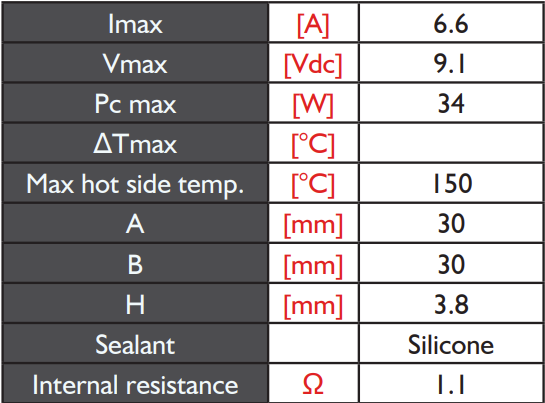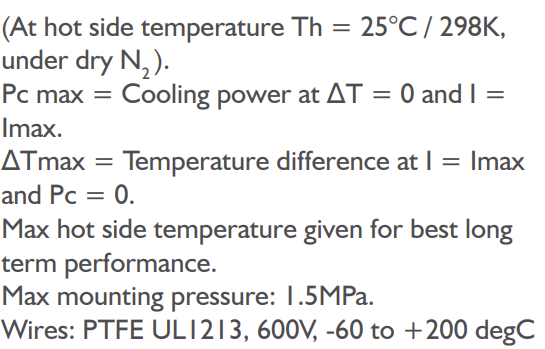

# Delta T_max Estimation

T_h = T_hot_K(1);   %K

figure
hold on

x2plot = linspace(71,73,21)';

xpred = [repmat(data_max.I_max, length(x2plot), 1), ...     %x1 = current
         x2plot, ...                                        %x2 = delta T
         repmat(T_h, length(x2plot), 1)];                   %x3 = T hot side in K
ypred = predict(mdl_Q_removed, xpred);

p_pred = plot(x2plot, ypred);
p_pred.HandleVisibility = 'off';
p_pred.LineStyle = '-';
p_pred.Color = 'r';

% Define a function handle for the prediction
fun = @(x) predict(mdl_Q_removed, [repmat(data_max.I_max, length(x), 1), x, repmat(T_h, length(x), 1)]);

% Find the zero around x = 72
x_zero = fzero(@(x) fun(x), 72);
fprintf('DeltaT_max = %.4f\n', x_zero);

DeltaT_max = 71.2668


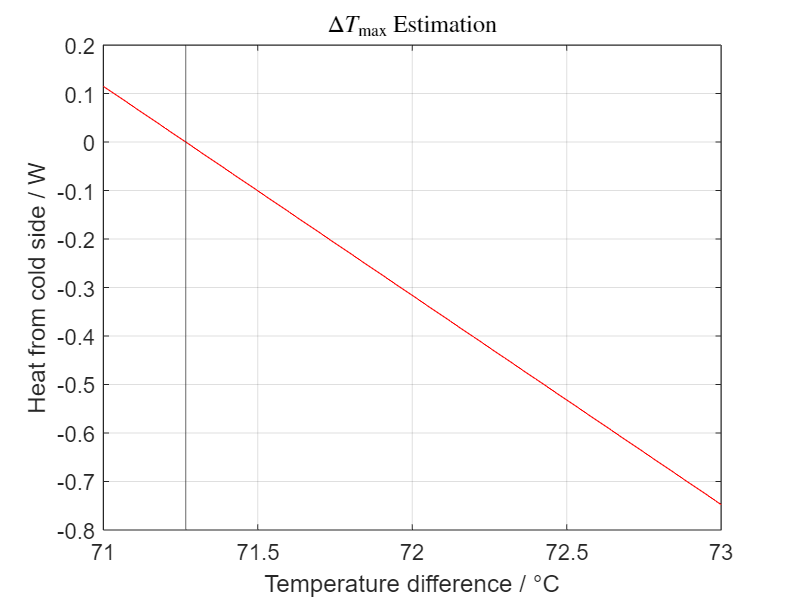

data_max.DeltaT_max = x_zero;
xline(x_zero)

xlabel(label_dict(headers_keys{3}));
ylabel(label_dict(headers_keys{5}));
title('$\Delta T_\mathrm{max}$ Estimation', Interpreter='latex')
grid on
box on

hold off

Parameters

% Figure of merit [1/K]
Z = 2*data_max.DeltaT_max / (T_h - data_max.DeltaT_max)^2

Z = 0.0028

% Seebeck voltage [V/K]
S_M = data_max.U_max / T_h

S_M = 0.0305

% Thermal conductance [W/K]
K_M = (T_h - data_max.DeltaT_max)*data_max.U_max*data_max.I_max / (2*T_h*data_max.DeltaT_max)

K_M = 0.3207

% Resistance [Ohm]
R_M = (T_h - data_max.DeltaT_max)*data_max.U_max / (T_h*data_max.I_max)

R_M = 1.0492

# Input Voltage

#### Voltage vs DeltaT 4every Current

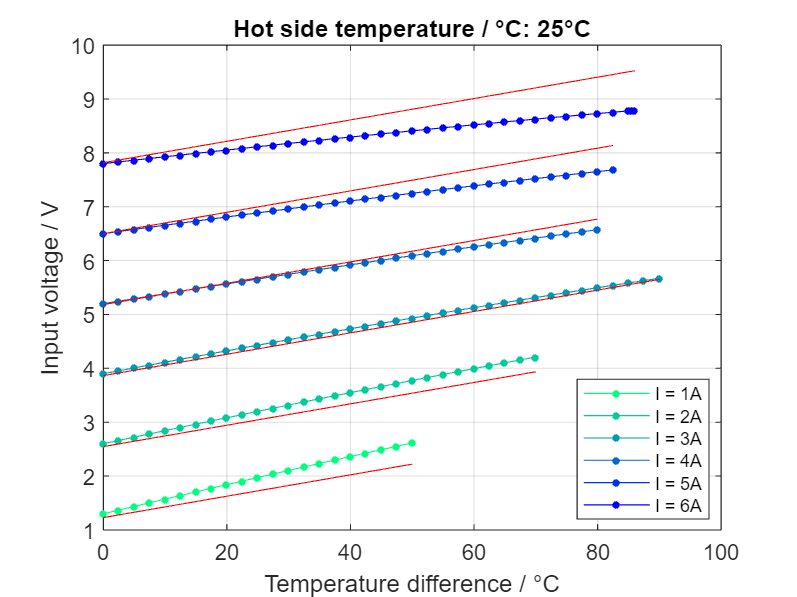

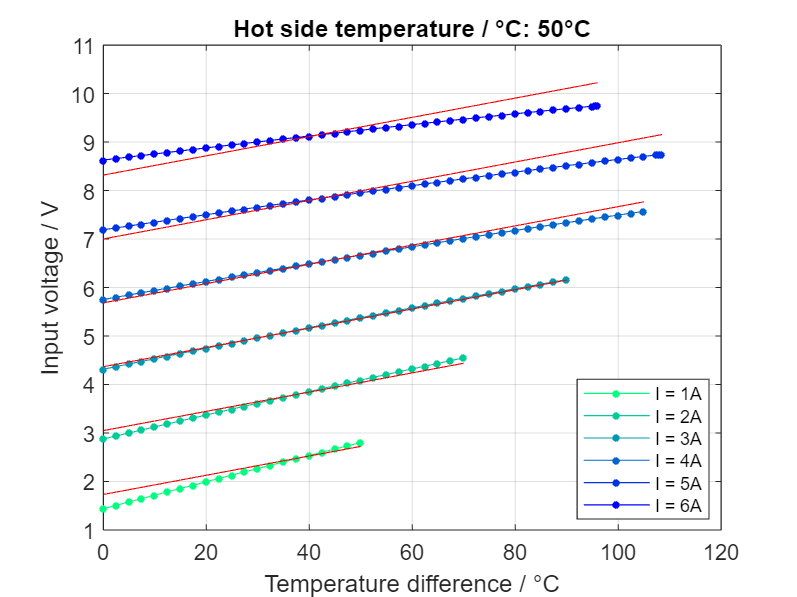

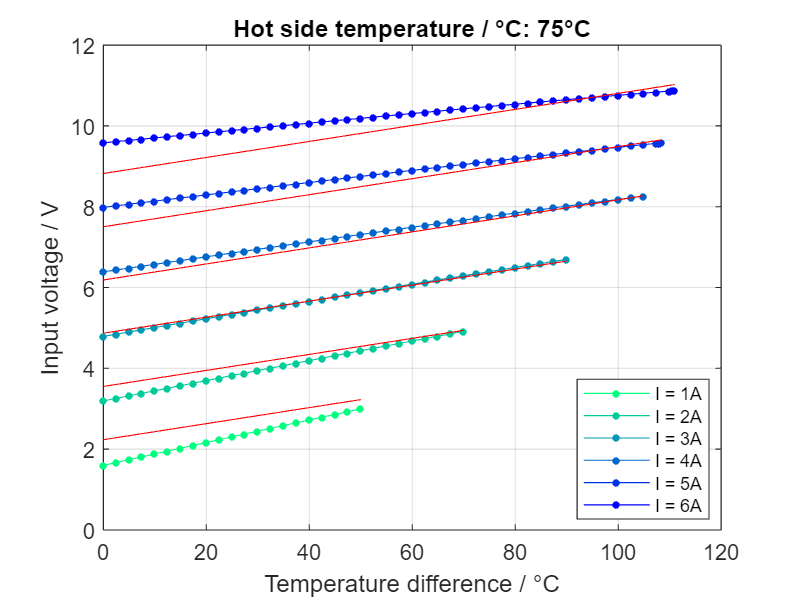

for j = 1:T_hot_len
    figure
    hold on
    
    for i = 1:curr_len
        mask = data.Current_A == curr(i) & data.Th_C == T_hot(j); % working also with °C
        x2plot = data.DeltaT_C(mask);
        y2plot = data.Voltage_V(mask);
    
        p = plot(x2plot, y2plot);
        p.DisplayName = legend_dict(headers_keys{4}) + curr_str(i) + units_dict(headers_keys{4});
        p.LineStyle = '-';
        p.Marker = '.';
        p.Color = curr_colormap(i,:);
        p.MarkerSize = 10;
    
        xpred = [repmat(curr(i), length(x2plot), 1), ...                    %x1 = current
                 x2plot, ...                                                %x2 = delta T
                 repmat(convtemp(T_hot(j), 'C', 'K'), length(x2plot), 1)];  %x3 = T hot side
        ypred = predict(mdl_voltage, xpred);
    
        p_pred = plot(x2plot, ypred);
        p_pred.HandleVisibility = 'off';
        p_pred.LineStyle = '-';
        p_pred.Color = 'r';
    end
    
    xlabel(label_dict(headers_keys{3}));
    ylabel(label_dict(headers_keys{2}));
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{1}) + ": " + T_hot_str(j) + units_dict(headers_keys{1}));
    grid on
    box on
    
    hold off
end

#### Voltage vs Current 4every DeltaT

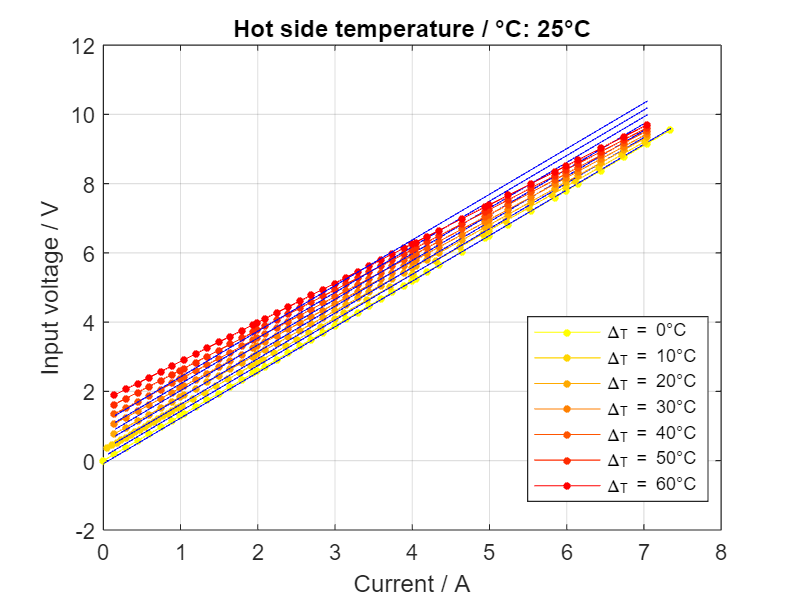

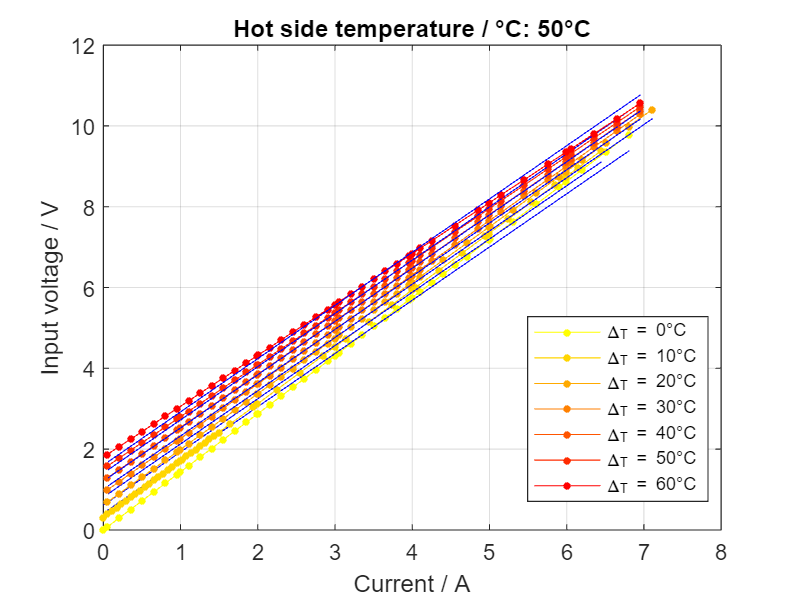

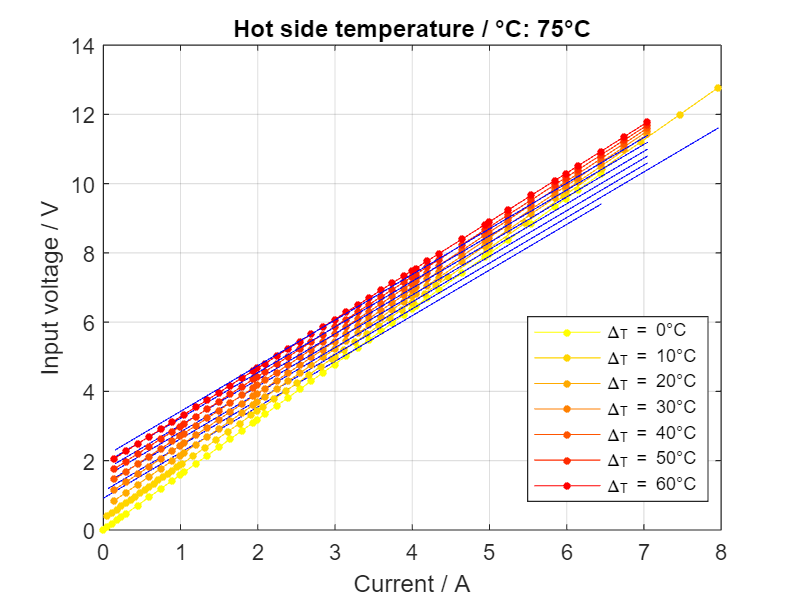

for j = 1:T_hot_len
    figure
    hold on
    
    for i = 1:deltaT_len
        mask = data.DeltaT_C == deltaT(i) & data.Th_C == T_hot(j);
        x2plot = data.Current_A(mask);
        y2plot = data.Voltage_V(mask);
    
        p = plot(x2plot, y2plot);
        p.DisplayName = legend_dict(headers_keys{3}) + deltaT_str(i) + units_dict(headers_keys{3});
        p.LineStyle = '-';
        p.Marker = '.';
        p.Color = deltaT_colormap(i,:);
        p.MarkerSize = 10;
    
        xpred = [x2plot, ...                                                %x1 = current
                 repmat(deltaT(i), length(x2plot), 1), ...                  %x2 = delta T
                 repmat(convtemp(T_hot(j), 'C', 'K'), length(x2plot), 1)];  %x3 = T hot side
        ypred = predict(mdl_voltage, xpred);
    
        p_pred = plot(x2plot, ypred);
        p_pred.HandleVisibility = 'off';
        p_pred.LineStyle = '-';
        p_pred.Color = 'b';
    end
    
    xlabel(label_dict(headers_keys{4}));
    ylabel(label_dict(headers_keys{2}));
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{1}) + ": " + T_hot_str(j) + units_dict(headers_keys{1}));
    grid on
    box on
    
    hold off
end

#### Voltage vs T_hot 4every DeltaT

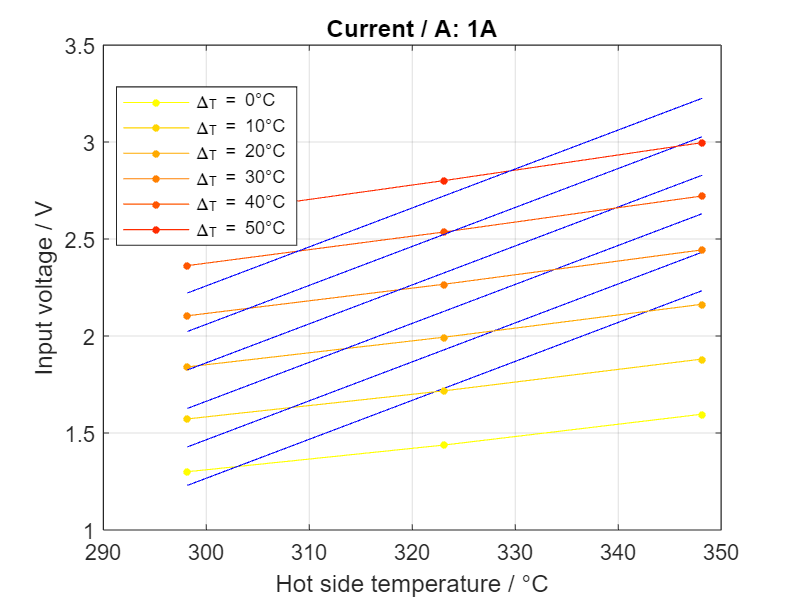

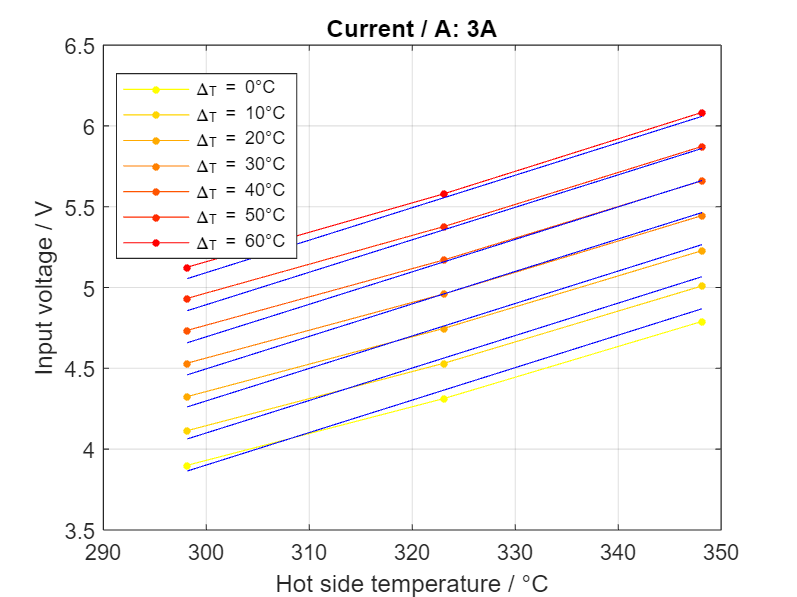

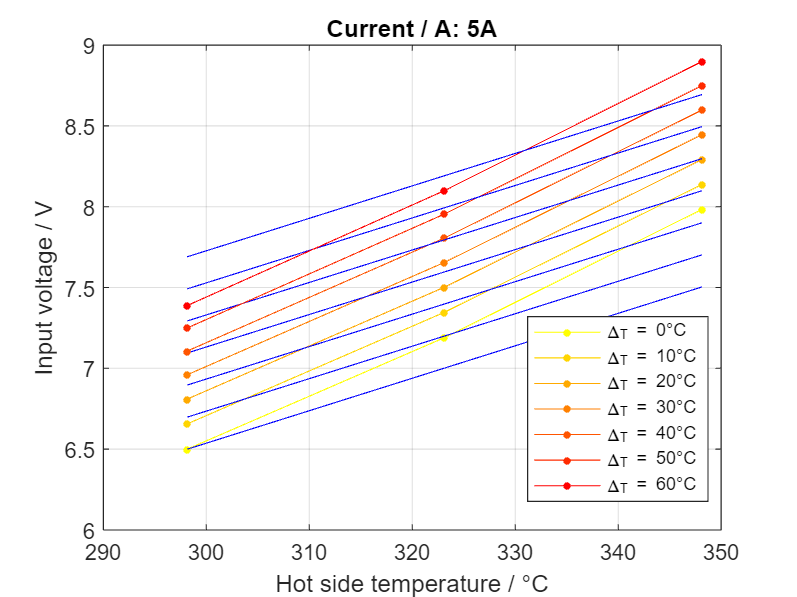

for j = 1:2:curr_len
    figure
    hold on
    
    for i = 1:deltaT_len
        mask = data.DeltaT_C == deltaT(i) & data.Current_A == curr(j);
        if ~any(mask)
            break
        end
        x2plot = convtemp(data.Th_C(mask), 'C', 'K');
        y2plot = data.Voltage_V(mask);
    
        p = plot(x2plot, y2plot);
        p.DisplayName = legend_dict(headers_keys{3}) + deltaT_str(i) + units_dict(headers_keys{3});
        p.LineStyle = '-';
        p.Marker = '.';
        p.Color = deltaT_colormap(i,:);
        p.MarkerSize = 10;
    
        xpred = [repmat(curr(j), length(x2plot), 1), ...            %x1 = current
                 repmat(deltaT(i), length(x2plot), 1), ...          %x2 = delta T
                 x2plot];                                           %x3 = T hot side
        ypred = predict(mdl_voltage, xpred);
    
        p_pred = plot(x2plot, ypred);
        p_pred.HandleVisibility = 'off';
        p_pred.LineStyle = '-';
        p_pred.Color = 'b';
    end
    
    xlabel(label_dict(headers_keys{1}));
    ylabel(label_dict(headers_keys{2}));
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{4}) + ": " + curr_str(j) + units_dict(headers_keys{4}));
    grid on
    box on
    
    hold off
end

# Electrical Power

#### P_el vs DeltaT 4every Current

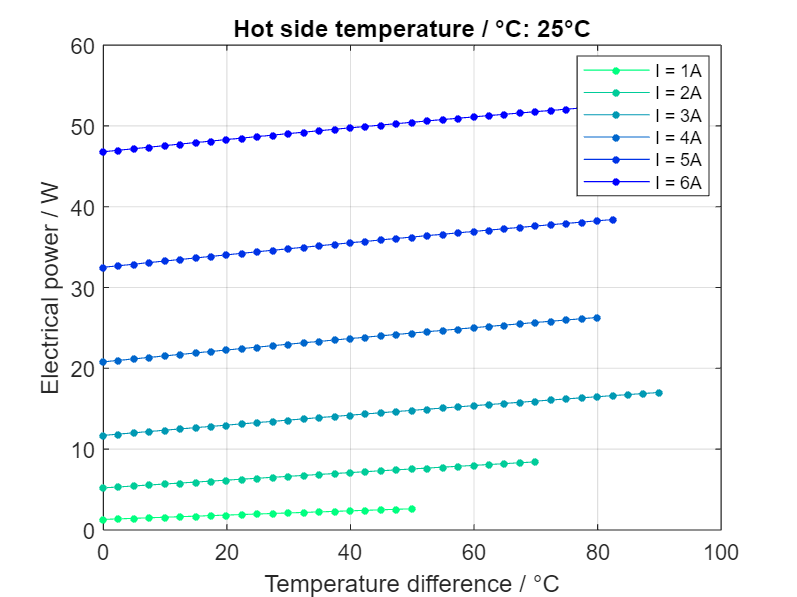

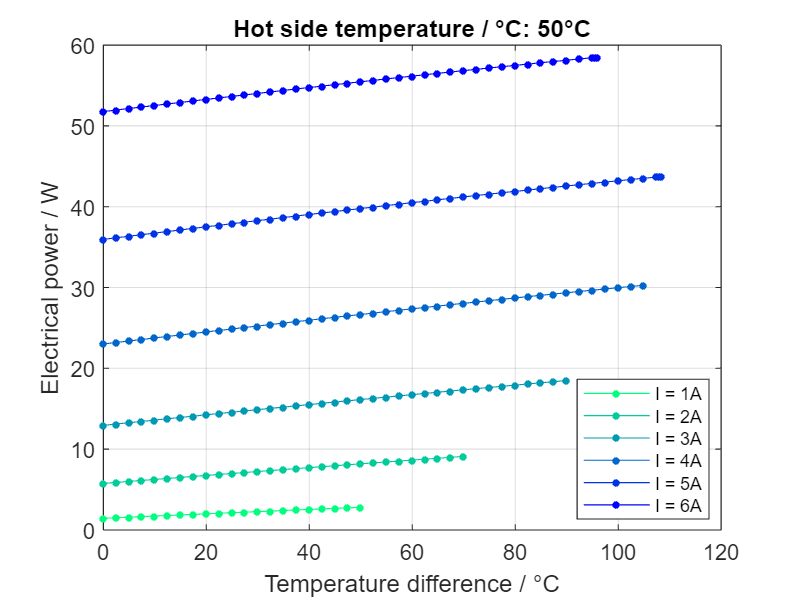

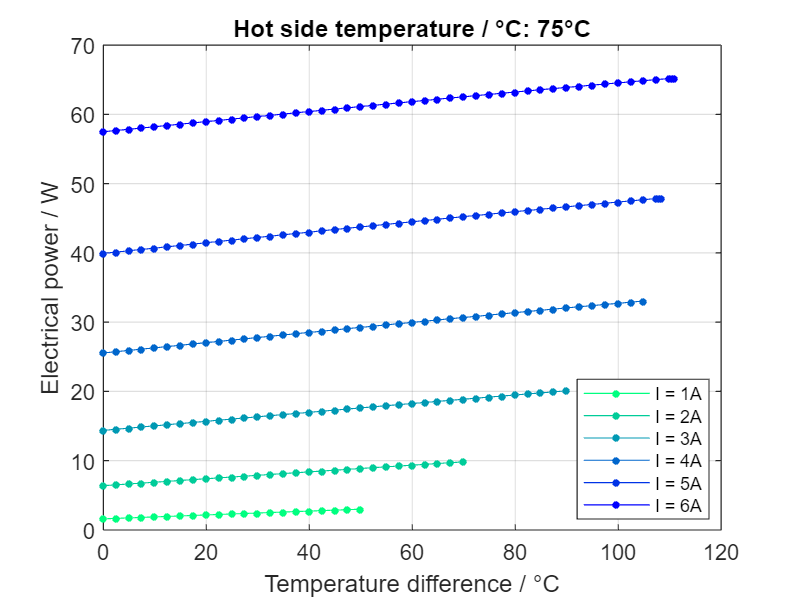

for j = 1:T_hot_len
    figure
    hold on
    
    for i = 1:curr_len
        mask = data.Current_A == curr(i) & data.Th_C == T_hot(j);
        x2plot = data.DeltaT_C(mask);
        y2plot = data.Voltage_V(mask) * curr(i);
    
        p = plot(x2plot, y2plot);
        p.DisplayName = legend_dict(headers_keys{4}) + curr_str(i) + units_dict(headers_keys{4});
        p.LineStyle = '-';
        p.Marker = '.';
        p.Color = curr_colormap(i,:);
        p.MarkerSize = 10;
    end
    
    xlabel(label_dict(headers_keys{3}));
    ylabel(label_P_el);
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{1}) + ": " + T_hot_str(j) + units_dict(headers_keys{1}));
    grid on
    box on
    
    hold off
end

# Heat from cold side Q_in or Q_c

#### Q_c vs DeltaT 4every Current

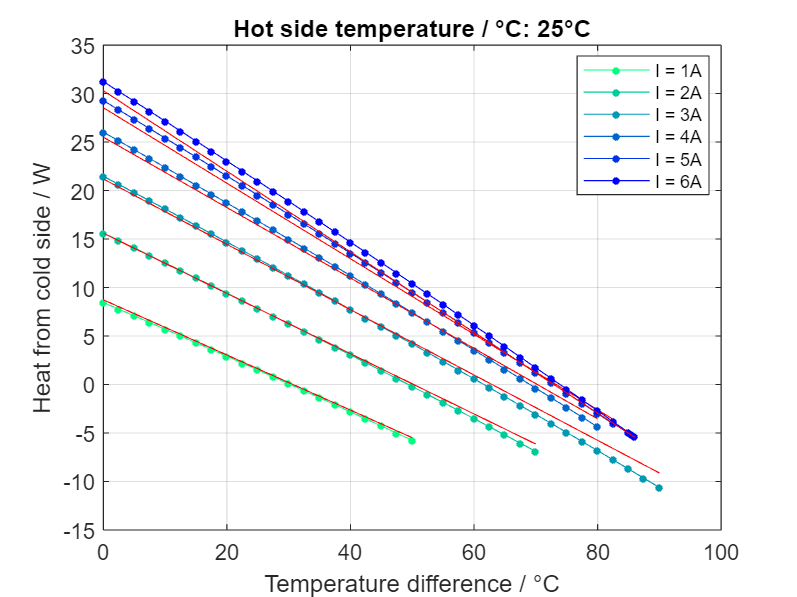

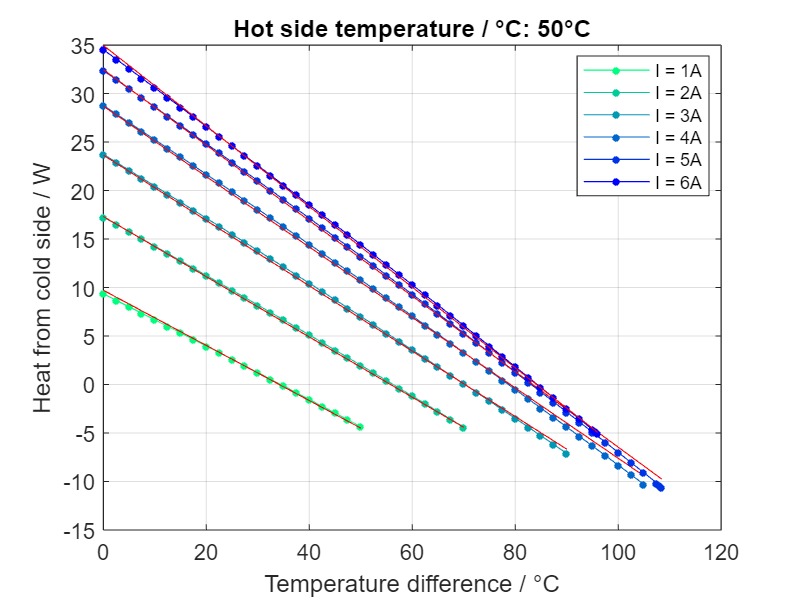

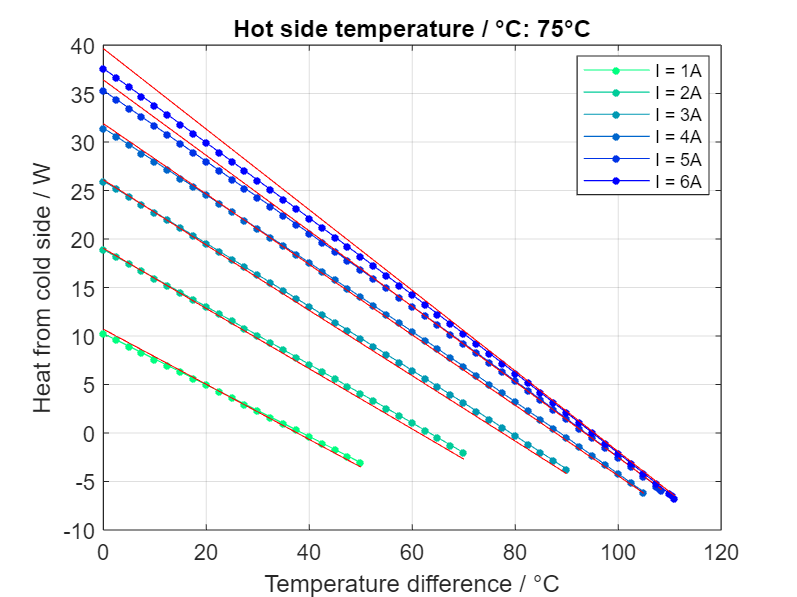

for j = 1:T_hot_len
    figure
    hold on
    
    for i = 1:curr_len
        mask = data.Current_A == curr(i) & data.Th_C == T_hot(j);
        x2plot = data.DeltaT_C(mask);
        y2plot = data.Qremoved_W(mask);

        % Sort x and y values
        sorted2plot = sortrows([x2plot, y2plot], 1);
        x2plot = sorted2plot(:, 1);
        y2plot = sorted2plot(:, 2);
    
        p = plot(x2plot, y2plot);
        p.DisplayName = legend_dict(headers_keys{4}) + curr_str(i) + units_dict(headers_keys{4});
        p.LineStyle = '-';
        p.Marker = '.';
        p.Color = curr_colormap(i,:);
        p.MarkerSize = 10;
    
        xpred = [repmat(curr(i), length(x2plot), 1), ...                    %x1 = current
                 x2plot, ...                                                %x2 = delta T
                 repmat(convtemp(T_hot(j), 'C', 'K'), length(x2plot), 1)];  %x3 = T hot side
        ypred = predict(mdl_Q_removed, xpred);
    
        p_pred = plot(x2plot, ypred);
        p_pred.HandleVisibility = 'off';
        p_pred.LineStyle = '-';
        p_pred.Color = 'r';
    end
    
    xlabel(label_dict(headers_keys{3}));
    ylabel(label_dict(headers_keys{5}));
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{1}) + ": " + T_hot_str(j) + units_dict(headers_keys{1}));
    grid on
    box on
    
    hold off
end

#### Q_c vs Current 4every DeltaT

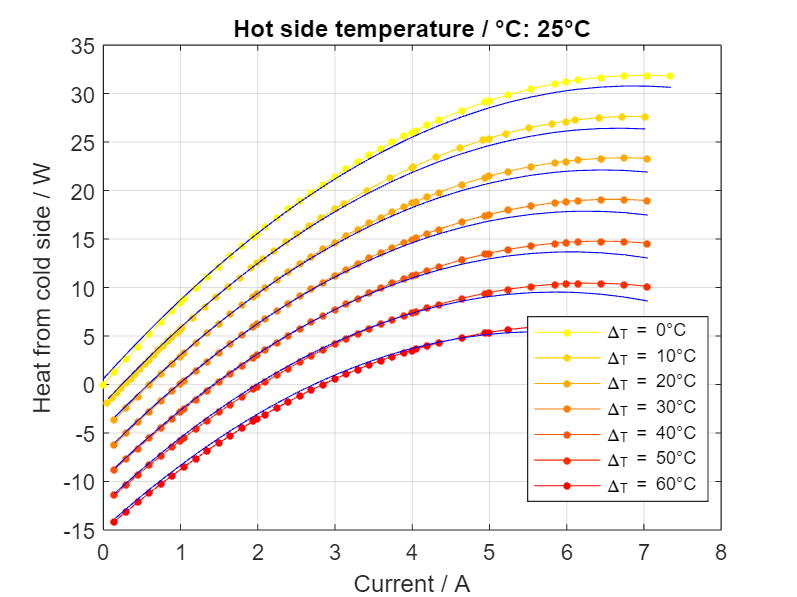

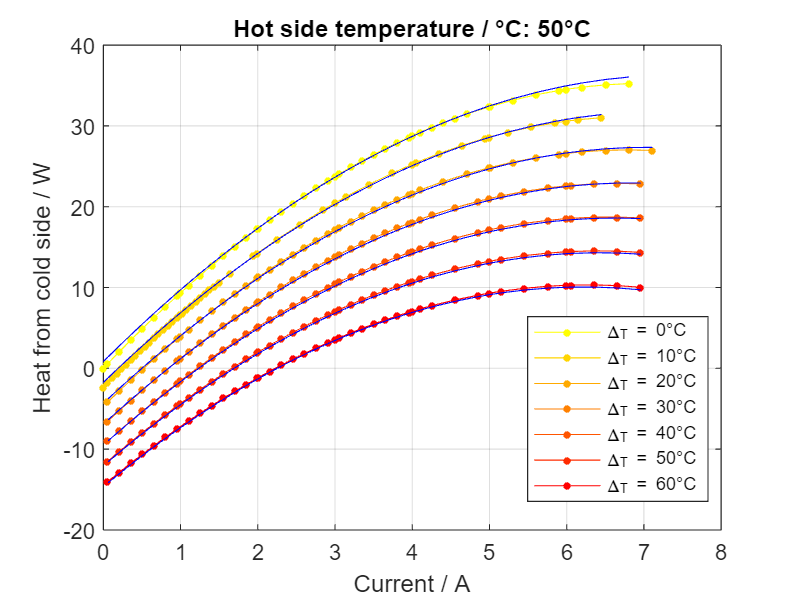

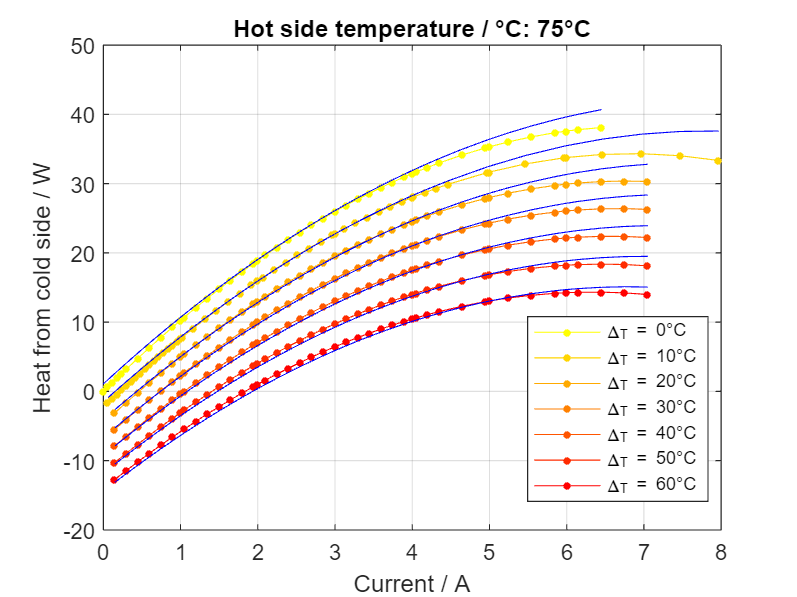

for j = 1:T_hot_len
    figure
    hold on
    
    for i = 1:deltaT_len
        mask = data.DeltaT_C == deltaT(i) & data.Th_C == T_hot(j);
        x2plot = data.Current_A(mask);
        y2plot = data.Qremoved_W(mask);

        % Sort x and y values
        sorted2plot = sortrows([x2plot, y2plot], 1);
        x2plot = sorted2plot(:, 1);
        y2plot = sorted2plot(:, 2);
    
        p = plot(x2plot, y2plot);
        p.DisplayName = legend_dict(headers_keys{3}) + deltaT_str(i) + units_dict(headers_keys{3});
        p.LineStyle = '-';
        p.Marker = '.';
        p.Color = deltaT_colormap(i,:);
        p.MarkerSize = 10;
    
        xpred = [x2plot, ...                                                %x1 = current
                 repmat(deltaT(i), length(x2plot), 1), ...                  %x2 = delta T
                 repmat(convtemp(T_hot(j), 'C', 'K'), length(x2plot), 1)];  %x3 = T hot side
        ypred = predict(mdl_Q_removed, xpred);
    
        p_pred = plot(x2plot, ypred);
        p_pred.HandleVisibility = 'off';
        p_pred.LineStyle = '-';
        p_pred.Color = 'b';
    end
    
    xlabel(label_dict(headers_keys{4}));
    ylabel(label_dict(headers_keys{5}));
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{1}) + ": " + T_hot_str(j) + units_dict(headers_keys{1}));
    grid on
    box on
    
    hold off
end

#### Q_c vs T_hot 4every DeltaT

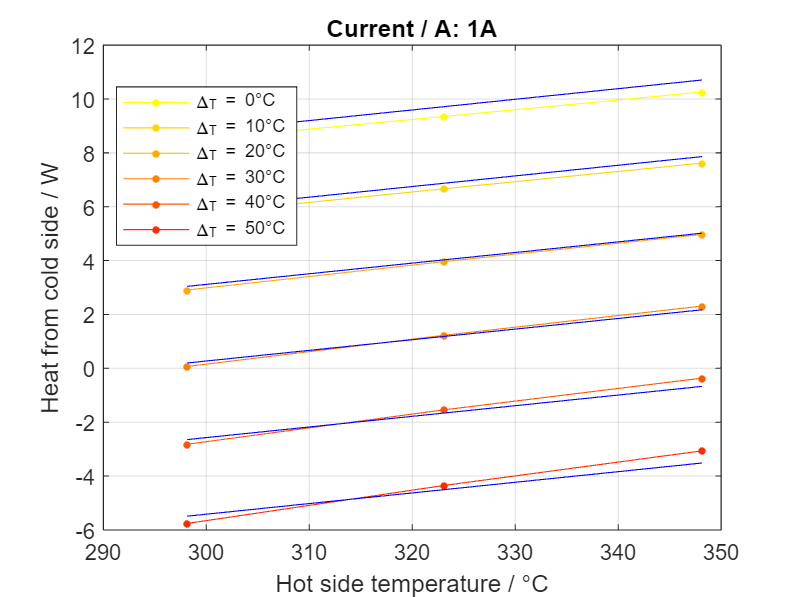

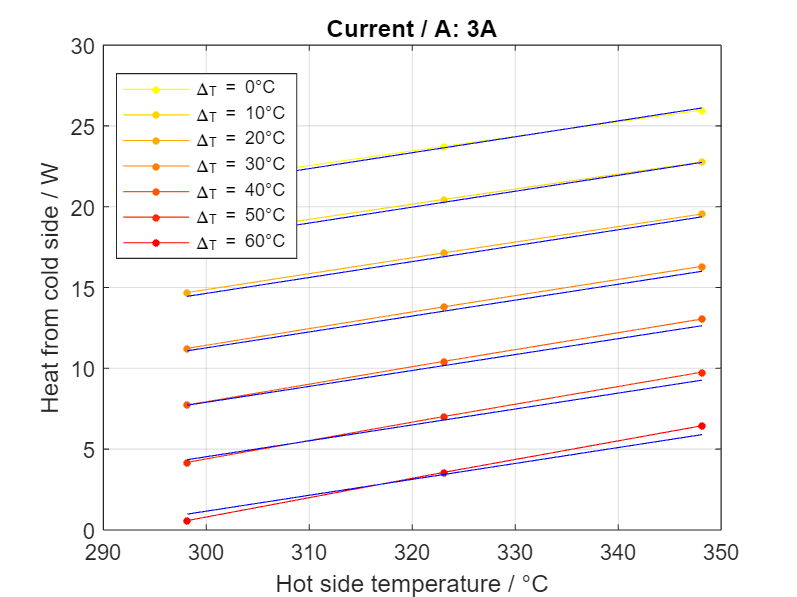

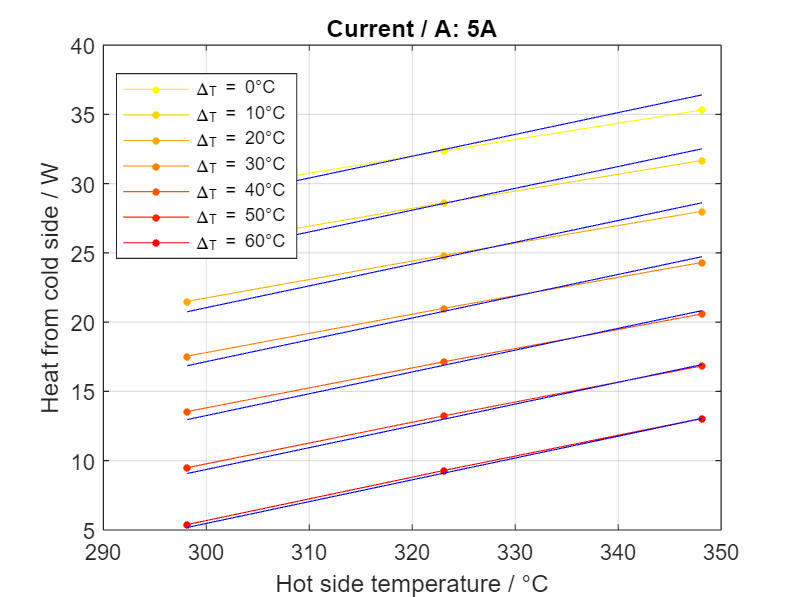

for j = 1:2:curr_len
    figure
    hold on
    
    for i = 1:deltaT_len
        mask = data.DeltaT_C == deltaT(i) & data.Current_A == curr(j);
        if ~any(mask)
            break
        end
        x2plot = convtemp(data.Th_C(mask), 'C', 'K');
        y2plot = data.Qremoved_W(mask);

        % Sort x and y values
        sorted2plot = sortrows([x2plot, y2plot], 1);
        x2plot = sorted2plot(:, 1);
        y2plot = sorted2plot(:, 2);
    
        p = plot(x2plot, y2plot);
        p.DisplayName = legend_dict(headers_keys{3}) + deltaT_str(i) + units_dict(headers_keys{3});
        p.LineStyle = '-';
        p.Marker = '.';
        p.Color = deltaT_colormap(i,:);
        p.MarkerSize = 10;
    
        xpred = [repmat(curr(j), length(x2plot), 1), ...            %x1 = current
                 repmat(deltaT(i), length(x2plot), 1), ...          %x2 = delta T
                 x2plot];                                           %x3 = T hot side
        ypred = predict(mdl_Q_removed, xpred);
    
        p_pred = plot(x2plot, ypred);
        p_pred.HandleVisibility = 'off';
        p_pred.LineStyle = '-';
        p_pred.Color = 'b';
    end
    
    xlabel(label_dict(headers_keys{1}));
    ylabel(label_dict(headers_keys{5}));
    lg = legend('Location','best');
    lg.FontSize = 8;
    title(label_dict(headers_keys{4}) + ": " + curr_str(j) + units_dict(headers_keys{4}));
    grid on
    box on
    
    hold off
end